# temp1911 automatically identify vessels in Doppler en face images

Dock figure(1) and use [this layout](https://docs.google.com/document/d/1RuEO2t5K-t82QPUK-sShLjorJyRC5uLGxchojfOiYDs/edit#heading=h.3m49wo5vra7y) and clear all output.

## 30. Initiate.

You can ignore a warning message (orange color) here. The values in the instruction below are default values. 

- aid : Analysis ID to load, the one you used in "2 Register Doppler.mlx"

- aid2 : Analysis ID to save a result from this script of tracking the blood flow.

comInit;

uid = 'kwalek';  % User ID
aid = 'ad9-doppler';  % to load
aid2 = 'ad9-doppler-flow-jlee';  % to save

pathdata = ['D:\' uid '\'];  % path to save the analysis result
pathrepo = ['\\files.brown.edu/Research/ENG_Lee-Lab_Shared/group/report/ad-16-ko-mouse/Angiogram/3 Track diameter # ' uid ' # ' aid2];  % path of report figures

sec30;

Registered Doppler data loaded.  The data used the following analysis options:


ap = struct with fields:
    oini: 3
      xx: [1×420 double]
      yy: [1×419 double]


## 31. Navigate *en face *slices and set the representative depth of each.

Set parameters and run this section.  Values in the instruction below means default. 

- dz = 4 : The number of voxels to move in depth.

- zavg = 2 : The number of *en face *slices to be averaged.  +/-zavg slices will be averaged.

- limV = 5*[-1 1] : The color range of the velocity [mm/s]

UI keys

- Q: Quit.

- G: Select a depth manually.

- E/D: Decrease/increase the depth of monitoring.

- S/F: Move to the previous/next session.

Tip: When you registered images in *2 Register Doppler.mlx*, you chose depths so that you can see structural features across sections.  However, in this flow measurement, it is better to choose depths where most vessels appear circular.  This section will begin with the depths you selected in *2 Register Doppler.mlx*, and the vessels may appear more circular if you go deeper by a few steps.

SECTION 31 RUNNING ...


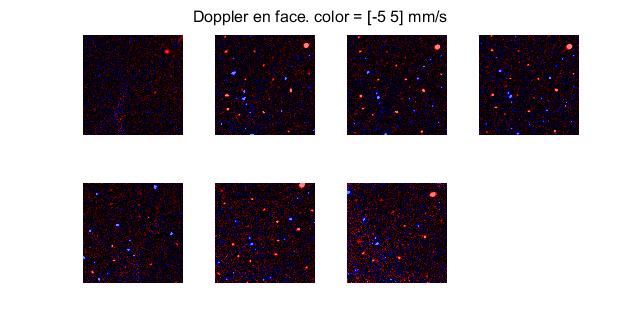

SECTION 31 COMPLETED.


dz = 4;
zavg = 2;
limV = 5*[-1 1];

sec31;

## 32. Select vessels to track changes in the blood flow and vessel diameter.

If you cannot find many of the same vessels across sessions, you can go back to and run Section 31 again.  

This section shows the flow results only at the end to avoid any operator bias.

If you want to reset and restart this section, execute "*clear V*".  

If you want to see the values of flow [uL/min] and diameter [um], double-click the variables *Vf* and *Vd*, respectively.

Parameters:

- nv = 20 : The number of vessels.  Max = 20.

- nxwin = 40 : The size of the window for each vessel.

- bEzero = true : Whether to force the offset in a Gaussian fitting to be zero.

- limV2 = [-1 1]*10 : The color range of the velocity in this white background.  It's better to set this larger than the *limV *above.

UI keys:

- Q : Quit.

- G : Select a vessel.

- E/D : Move to the previous/next vessel.

- S/F : Move to the previous/next dataset.

SECTION 32 RUNNING ...


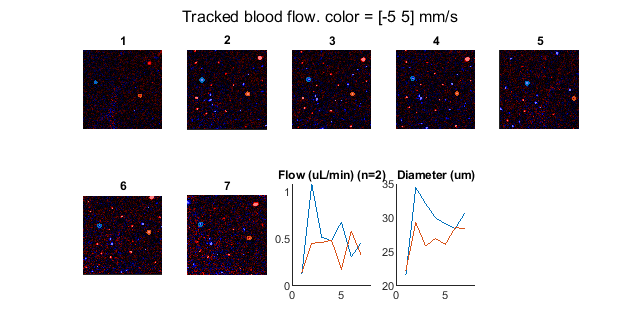

SECTION 32 COMPLETED.


nv = 20;
nxwin = 40;
bEzero = true;
limV2 = [-1 1]*10;

sec32;

## 33. Set an ROI to track a change in the regional blood flow.

Set the ROI and then run Section 33a.  No need to push G or Q keys or to double-click the ROI. 

sec33;

### 33a. Track a change in the regional blood flow.

After you set the ROI, run this section.  If you want to set the ROI again, run Section 33 again.

If you want to see the values of regional flow [uL/min], double-click the variable *F*, the columns of which represent "both", "arterioles only", and "venules only".

Parameters:

- vArt = 1.0 : Decending flow with a higher velocity than this threshold [mm/s] will be considered arteriolar flow.

- vVen = -1.0 : Ascending flow with a lower velocity than this threshold will be considered venular flow.

SECTION 33a RUNNING ...


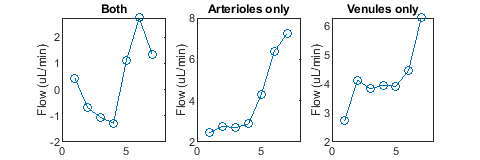

SECTION 33a COMPLETED.


vArt = 1;
vVen = -1;

sec33a;

## 39. Save.

fpath = [pathdata aid2 '.mat'];
if ~isempty(dir(fpath))
    disp('Overwriting ...');
else
    disp('Saving ...');
end

Saving ...


clear cVV VV img;
save('-v7.3',fpath);
disp('Analysis saved');

Analysis saved
